# **************Computational Electromagnetics 

## *********************************** Hw3

*******************Mohammadreza Arani         :::::::::::::         810100511

*************************************************1401/08/23   

## Q-3.30:   

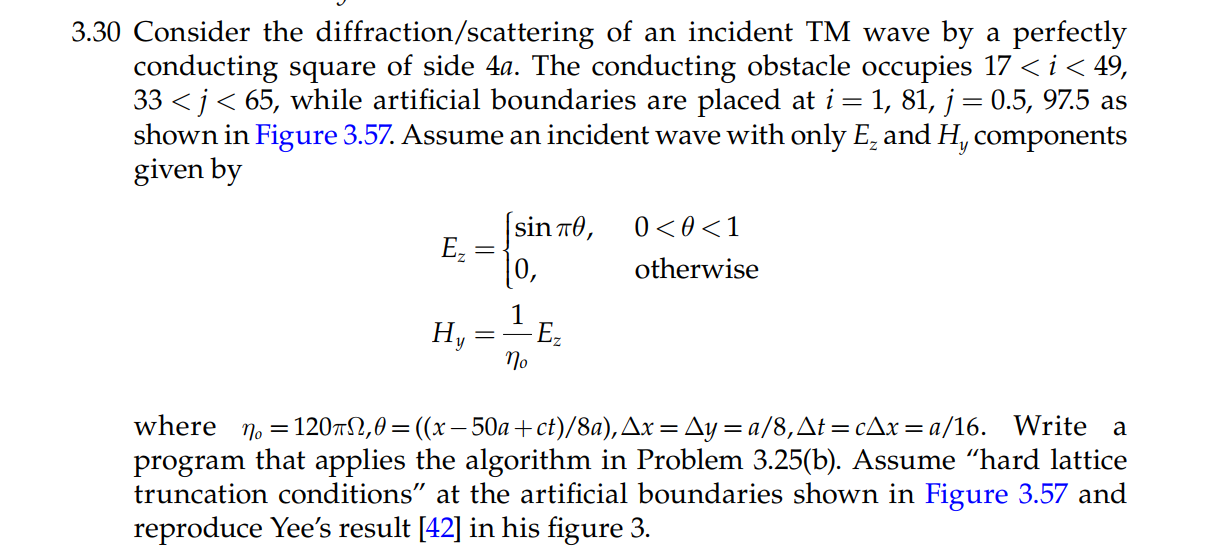

Where the Figure 3.57 is:

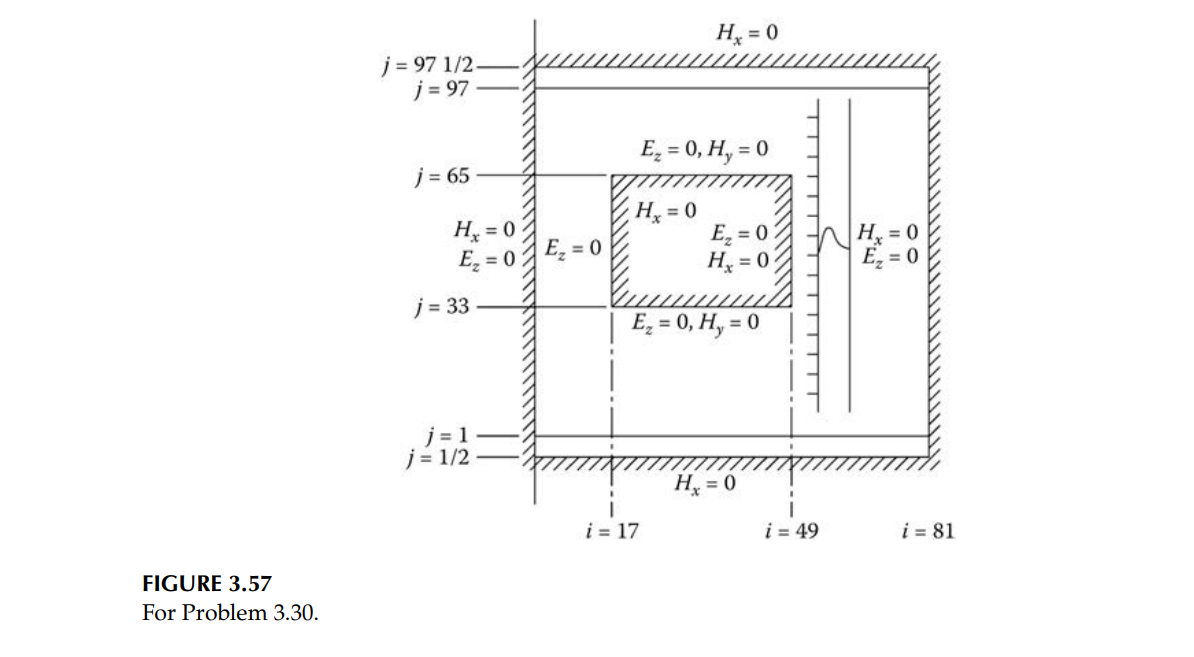

Here, we have to follow Yee's work to reach the desired results! --> The Yee's results are:

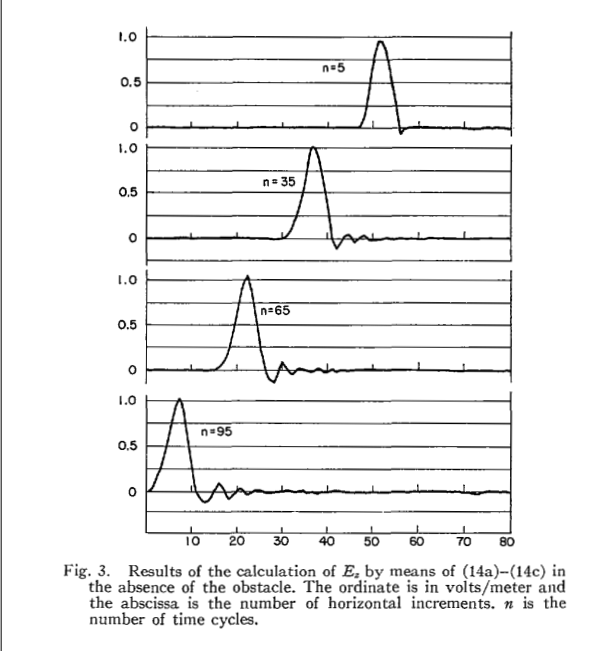

which are based on the following equations:

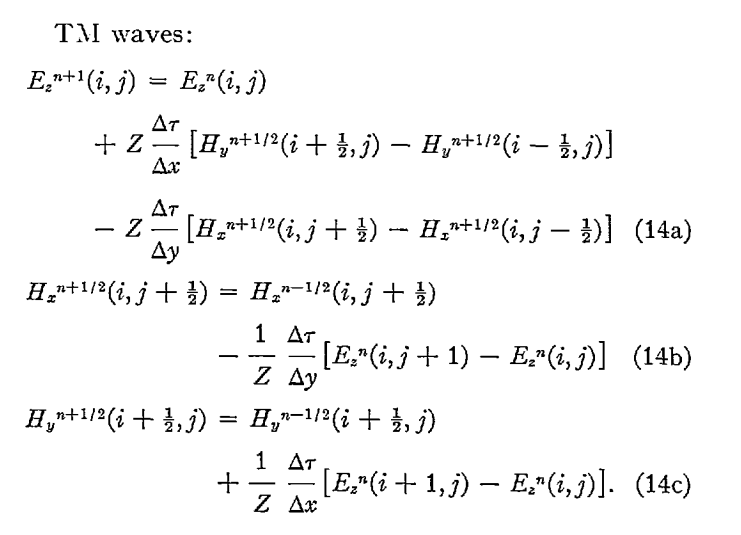

% TM wave --> we have Ez !=0  and Hz=0; Also d/dz=0;  ||||    Scattering/Diffraction   ||||||  PEC --> 4a *  4a  |||||
% 

% Given Indexes:
% i = 1:81*2;
% j = 0.5*2:97.5*2;


% Incident Wave with Only Ez , Hy --> a Plane Wave!   Ez  = sin(pi*theta);
%                                                     Hy  = 1/eta0 * Ez;
%                                                     eta0 = 120*pi; 
%   theta  = (x-50*a+ct)/(8a);
%                                                     
%   delta_x  = delta_y   = a/8; 
%   delta_t =  c*delta_x = a/16;
%                                                     
%  Assume Hard Lattice Truncation Conditions
%  Problem 3.25(b):

## Initializations:

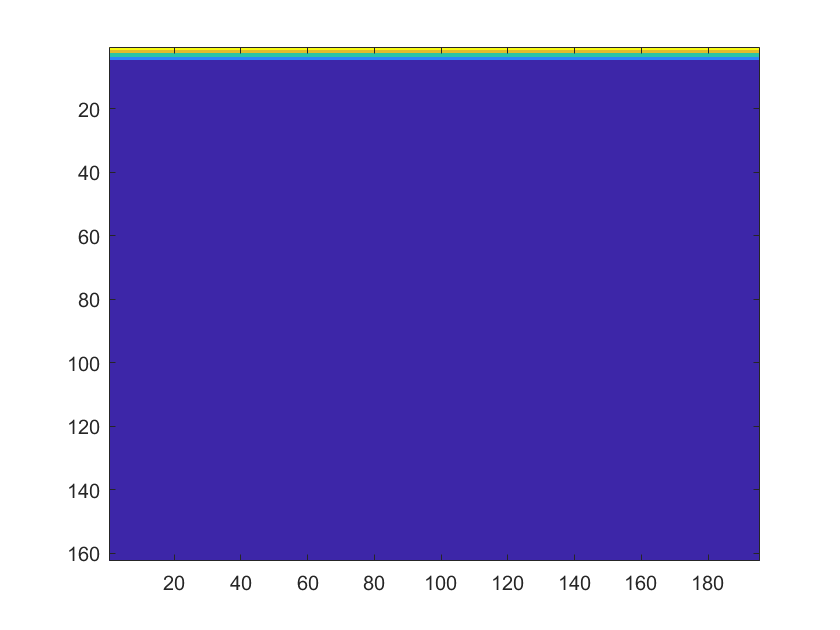

clear; clc;close all;
a = 2;

eta0 =120*pi ; % [ohm]
delta_x = a/8;
delta_y = delta_x;

delta_t = a/16;
c = delta_t/delta_x *2;

Tmax = 14;

Lx = 81*2;
Ly = 97.5*2 ;

X = linspace(0,1/2*Lx/8,Lx) ;
T = 0:delta_t:Tmax ;

Lt = length(T);

Ez = zeros(Lx,Ly,Lt);
Hx = Ez;

for t=1:Lt-2
    for i=1:81*2
        theta = ( i-50*a+c*t  )/(8*a) ;
        if((0<theta) && (theta<1))  % Source Generation:
            Ez(i,:,t) = sin(pi*theta) ;
            Hx(i,:,t) = Ez(i,j,t)/eta0;
        end

        for j=0.5*2:97.5*2-3
            if ((i==1)||(i==81*2))  % Hard Boundary at i=1,81*2
                % Continue
            else % Free Nodes:
                Ez(i,j,t+1) =  Ez(i,j,t+1) - eta0*1* (Hx(i,j+2,t+1) - Hx(i,j,t+1))  ; % Maxwell's EQ
                Hx(i,j,t+1) =  Hx(i,j+1,t+1)  - 1/(eta0) * 1* (Ez(i,j+1,t+1) -Ez(i,j,t+1)    );
            end
        end
    end
    figure(1)
    imagesc(Ez(:,:,t))
    drawnow
end

## Plot the Results:

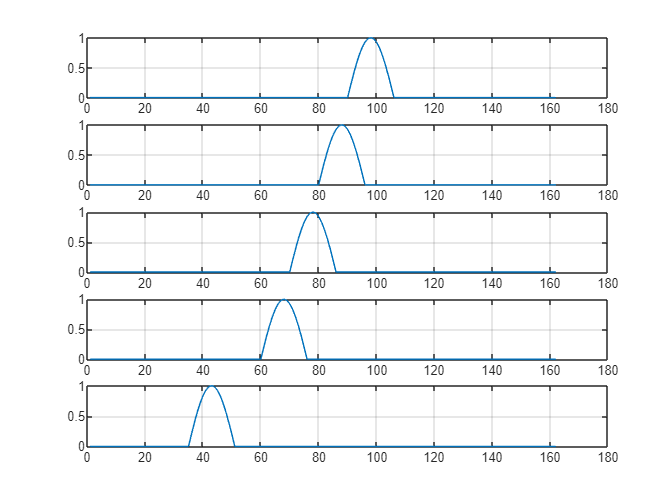


figure(3)
subplot(5,1,1)
plot(Ez(:,10,10));
grid on
subplot(5,1,2)
plot(Ez(:,10,20));
grid on
subplot(5,1,3)
plot(Ez(:,10,30));
grid on
subplot(5,1,4)
plot(Ez(:,10,40));
grid on
subplot(5,1,5)
plot(Ez(:,10,65));
grid on

We can see the propagation of the wave in time!  --> In the absence of the obstacle!

In the presence of the obstacle we have:

## FDTM with Obstacle:

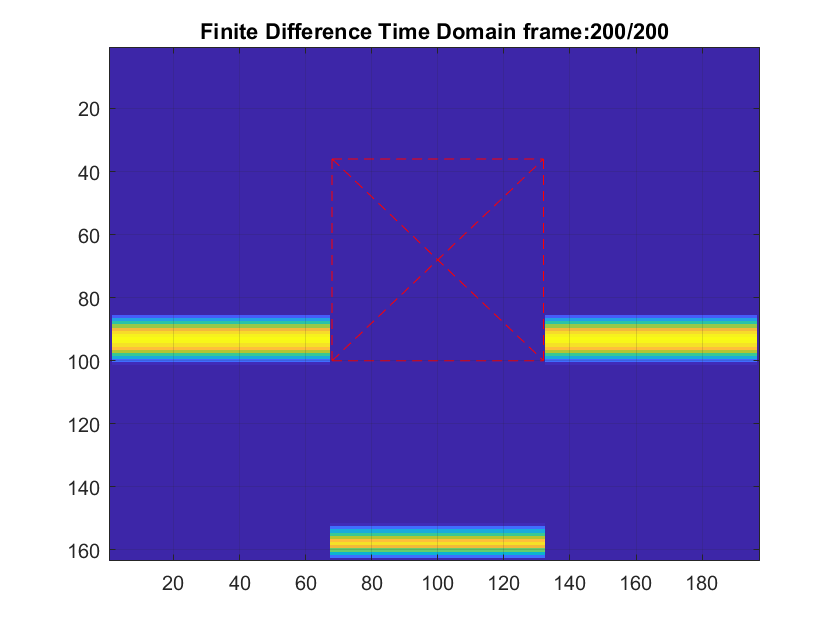

H = 0.05; NT = 200;
A = 8.10; B = 9.75;
NX = fix(A/H); NY = fix(B/H);
Z = 376.7;  % Equals to Eta0
alpha = 2; 
ct = 1/8;


% INITIALIZATION
    Ez = zeros(NX+2, NY+2); 
    Hy = zeros(NX+2, NY+2);
    Hx = zeros(NX+2, NY+2);        
% Source Generation
   for J=0:NY-1
       for I=0:NX-1
           theta = I - 50*alpha + ct;
           if (0<theta)&&(theta<8*alpha)
               theta;
              Ez(I+2,J+2) = sin(theta*pi/(8*alpha));
              Hy(I+2,J+2) = sin(theta*pi/(8*alpha))/Z;
           else
               %%% do nothing
           end
       end
   end  

%CALCULATE Fields AT FREE POINT
    for K=1:NT
        for I=0:NX-1
            for J=0:NY-1
               if ((17*2<=I)&&(I<=49*2))&&((33*2<=J)&&(J<=65*2))  
                    %Continue
               else                                   
                    Hx(I+2,J+2,K+1) = Hx(I+2,J+2,K) - (1/Z)*( Ez(I+2,J+3,K) - Ez(I+2,J+2,K));
                    Hy(I+2,J+2,K+1) = Hy(I+2,J+2,K) + (1/Z)*( Ez(I+3,J+2,K) - Ez(I+2,J+2,K)); 
                    Ez(I+2,J+2,K+1) = Ez(I+2,J+2,K) + (Z)*  ( Hy(I+2,J+2,K+1) - Hy(I+1,J+2,K+1));
                    
               end                               
            end
        end
        % Animation of calculation
        figure(2); 
        imagesc(Ez(:,:,K+1));
        title("Finite Difference Time Domain frame:"+[num2str(K),'/',num2str(NT)])
        hold on
        plot(33*2*ones(1,10)+2,linspace(17*2,49*2,10)+2,'r--');
        plot(65*2*ones(1,10)+2,linspace(17*2,49*2,10)+2,'r--'); 
        plot(linspace(33*2,65*2,10)+2,17*2*ones(1,10)+2,'r--'); 
        plot(linspace(33*2,65*2,10)+2,49*2*ones(1,10)+2,'r--');
        plot(linspace(33*2,65*2,10)+2,linspace(17*2,49*2,10)+2,'r--')
        plot(linspace(33*2,65*2,10)+2,linspace(49*2,17*2,10)+2,'r--')
        hold off
        grid on
        drawnow
    end

The effect of the obstacle is obvious and the wave continues to propagate afterward! --> The wave shall be reflected when the incident wave hits the obtsacle!